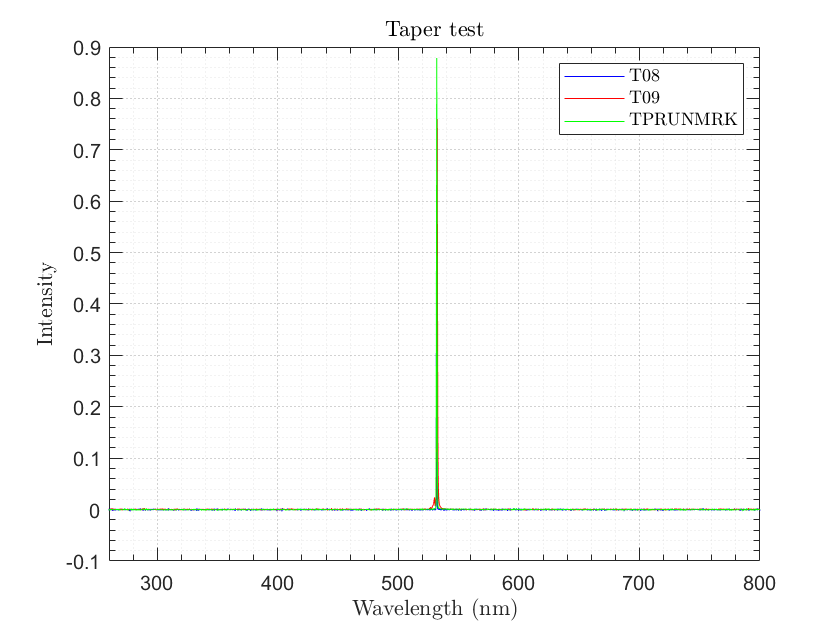

cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data'
% ================= Blue LED ================= %
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\TPRSpec.txt");
lambda = d(:,1);
Ia = d(:,2);
% Ia = normalize_intensity(Ia);
plot(lambda,Ia, "Color", [0 0 1])
title('Taper test',"Interpreter","latex");
xlabel('Wavelength (nm)', "Interpreter","latex");
ylabel('Intensity',"Interpreter","latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

hold on
% ================= Blue LED ================= %
d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\TPR09.txt");
lambda = d(:,1);
Ia = d(:,2);
% Ia = normalize_intensity(Ia);
plot(lambda,Ia, "Color", [1 0 0])

d = readmatrix("C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\TPRUNMRK.txt");
lambda = d(:,1);
Ia = d(:,2);
% Ia = normalize_intensity(Ia);
plot(lambda,Ia, "Color", [0 1 0])

xlim([260 800])
legend('T08', 'T09', 'TPRUNMRK', 'Interpreter', 'latex')
hold off